# Example: COVID-2019 data for US (cities and states)

I am still taking some data from John Hopkins university [1]. However, the format for the US data is different and not consistent. So the database may be updated in the next few days.

As far as I know (at last on 2020-03-04), no data for the recovered cases are (yet) available. The function fit_SEIQRDP is modified to account for this possibility.

The fitting is also slightly different than in the case where R is available: The (pseudo) death rate is first fitted and the coefficient identified this way are only allowed to change by +/-5 %. This is a pseudo death rate because the number of Confirmed-Deaths is used instead of Quarantined. The main fitting is then done using the heavily-constrained kappa values.

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Database access

The parameters are here taken as constant except the death rate and recovery rate.

clearvars;close all;clc;
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID_US();
timeRef = time;
tStart = datetime(2020,12,01); % initial time for the fitting
tEnd = datetime(2021,02,24); % Final time for the fitting

## Case of an entire state

Every city in one state is selected and the cases are added

Location = 'Washington'; % Find every cities in Washington state
% Location = 'New York'; % Find every cities in New York state
try
    indC = find(contains(tableConfirmed.Province_State,Location)==1);
    indD = find(contains(tableDeaths.Province_State,Location)==1);
catch exception
    searchLoc = strfind(tableConfirmed.Province_State,Location);
    indC = find(~cellfun(@isempty,searchLoc))  ;
    
    searchLoc = strfind(tableDeaths.Province_State,Location);
    indD = find(~cellfun(@isempty,searchLoc))   ;
end

% disp(tableConfirmed(indC,1:2))


% Initialisation
Confirmed = 0;
Deaths = 0;
Npop = 0;
for ii=1:numel(indC)
    Confirmed =  Confirmed + table2array(tableConfirmed(indC(ii),12:end));
end

for ii=1:numel(indD)
    Deaths =  Deaths + table2array(tableDeaths(indD(ii),13:end));
    Npop= Npop + table2array(tableDeaths(indD(ii),12)); % population (dummy number here)
end


Choice of the initial and final times

time = timeRef;
indT = find(time>=tStart & time <=tEnd);

Deaths = Deaths(indT);
time = time(indT);
Confirmed = Confirmed(indT);



fprintf(['Population = ',num2str(Npop),' \n'])

Population = 7614893 


% Definition of the first estimates for the parameters
alpha_guess = 0.05;
beta_guess = 0.8; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.5; % rate at which infectious people enter in quarantine
lambda_guess = [0.1,0.1,10]; % recovery rate
kappa_guess = [0.01,0.01,10]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    Q_guess,...
    lambda_guess,...
    kappa_guess];

E0 = 0.25*Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = 0.5*E0; % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1)-Deaths(1);
R0 = Deaths(1); % Unknown but unlikely to be zero. Taken as equal to the number of deaths
D0 = Deaths(1);

% Parameter estimation with the lsqcurvefit function[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun] = ...
    fit_SEIQRDP(Confirmed-Deaths,[],Deaths,Npop,E0,I0,time,guess,'Display','off');

Simulate the epidemy outbreak based on the fitted parameters

dt = 1/24; % time step
time1 = datetime(time(1), 'Locale', 'en_US'):dt:datetime(time(end)+datenum(10), 'Locale', 'en_US');
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,...
    gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t,lambdaFun,kappaFun);

#### Display the fitted and measured (pseudo) death rates

This is a "pseudo" death rate because it si calculated based on (Q(t)+R(t)) and not only from Q(t).

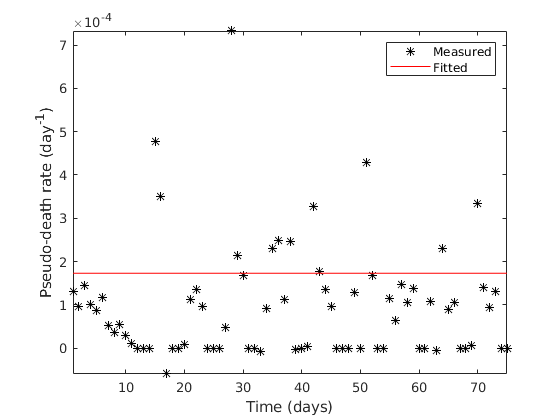

checkRates(time,Confirmed-Deaths,[],Deaths,kappaFun,lambdaFun,Kappa1,Lambda1);

Comparison of the fitted and real data

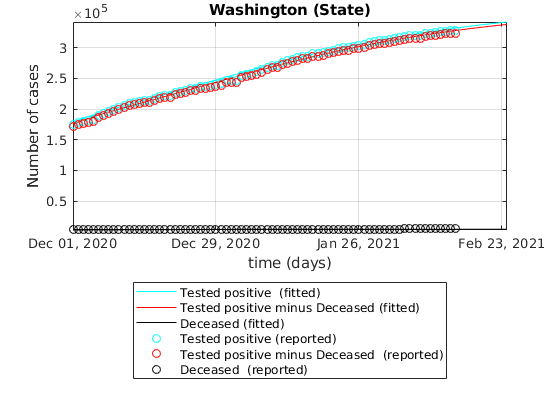

figure
semilogy(time1,Q+R+D,'c',time1,Q+R,'r',time1,D,'k');
hold on
semilogy(time,Confirmed,'co',time,Confirmed-Deaths,'ro',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Tested positive  (fitted)','Tested positive minus Deceased (fitted)',...
    'Deceased (fitted)',...
    'Tested positive (reported)',...
    'Tested positive minus Deceased  (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
title([Location,' (State)'])
set(gca,'yscale','lin')

## Example of a single city

time = timeRef;

fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 14-Feb-2021


Location = 'New York, New York, US';


try
    indC = find(contains(tableConfirmed.Combined_Key,Location)==1);
    indD = find(contains(tableDeaths.Combined_Key,Location)==1);
catch exception
    searchLoc = strfind(tableConfirmed.Combined_Key,Location);
    indC = find(~cellfun(@isempty,searchLoc))  ;
    
    searchLoc = strfind(tableDeaths.Combined_Key,Location);
    indD = find(~cellfun(@isempty,searchLoc))   ;
end

disp(tableConfirmed(indC,11));

          Combined_Key      
    ________________________

    "New York, New York, US"



indC = indC(1);
indD  = indD(1);

Deaths = table2array(tableDeaths(indD,13:end));
Confirmed = table2array(tableConfirmed(indC,12:end));
Npop= table2array(tableDeaths(indD,12)); % population (dummy number here)

Choice of initial and final times

indT = find(time>=tStart & time <=tEnd);
Deaths = Deaths(indT);
time = time(indT);
Confirmed = Confirmed(indT);

fprintf(['Population = ',num2str(Npop),' \n'])

Population = 1628706 


% Definition of the first estimates for the parameters
alpha_guess = 0.05;
beta_guess = 0.8; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.5; % rate at which infectious people enter in quarantine
lambda_guess = [0.01,0.01,10]; % recovery rate
kappa_guess = [0.001,0.001,10]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    Q_guess,...
    lambda_guess,...
    kappa_guess];

E0 = 0.25*Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = 0.5*E0; % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1)-Deaths(1); %pseudo quarantined (unknown number of recovered)
D0 = Deaths(1);

% Parameter estimation with the lsqcurvefit function[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun] = ...
    fit_SEIQRDP(Confirmed-Deaths,[],Deaths,Npop,E0,I0,time,guess,'Display','off');

Simulate the epidemy outbreak based on the fitted parameters

dt = 1/24; % time step
R0 = 0; % set as zero since it is included in the variable Q-R
time1 = datetime(time(1), 'Locale', 'en_US'):dt:datetime(time(end)+datenum(10), 'Locale', 'en_US');
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,...
    gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t,lambdaFun,kappaFun);

Comparison of the fitted and real data

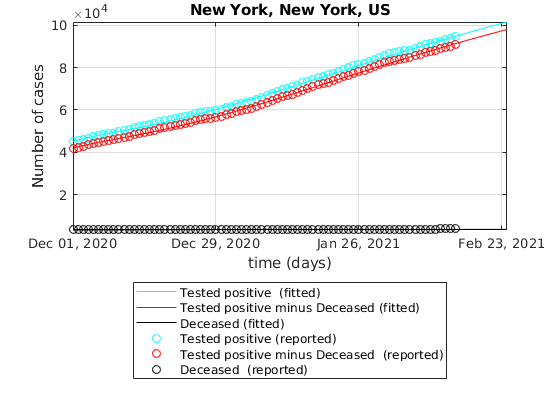

figure
semilogy(time1,Q+R+D,'c',time1,Q+R,'r',time1,D,'k');
hold on
semilogy(time,Confirmed,'co',time,Confirmed-Deaths,'ro',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Tested positive  (fitted)','Tested positive minus Deceased (fitted)',...
    'Deceased (fitted)',...
    'Tested positive (reported)',...
    'Tested positive minus Deceased  (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
title([Location])
set(gca,'yscale','lin')

#### Display the fitted and measured (pseudo) death rates

This is a "pseudo" death rate because it si calculated based on (Q(t)+R(t)) and not only from Q(t).

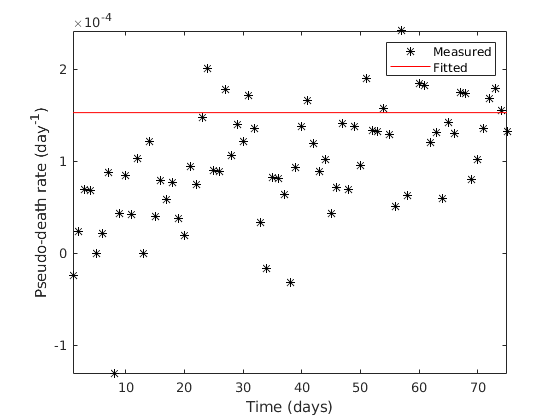

checkRates(time,Confirmed-Deaths,[],Deaths,kappaFun,lambdaFun,Kappa1,Lambda1);

## Case of multiple cities

The fitting is more challenging and uncertainties are indCreased because the number of recovered is unknown. In particular, the sensitivity on the initial guess is quite high. I have limited trust in the results provided by fit_SEIQRDP.

time = timeRef;
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 14-Feb-2021


            Combined_Key         
    _____________________________

    "Los Angeles, California, US"



Population = 10039107 


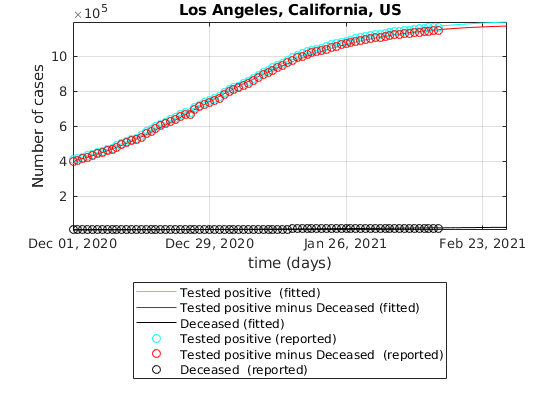

          Combined_Key       
    _________________________

    "Miami-Dade, Florida, US"



Population = 2716940 


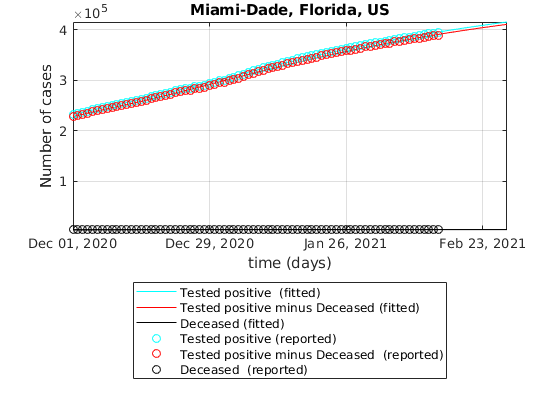

        Combined_Key    
    ____________________

    "Cook, Illinois, US"



Population = 5150233 


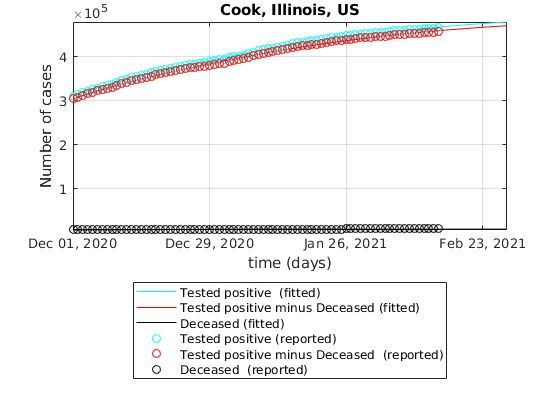

       Combined_Key    
    ___________________

    "Harris, Texas, US"



Population = 4713325 


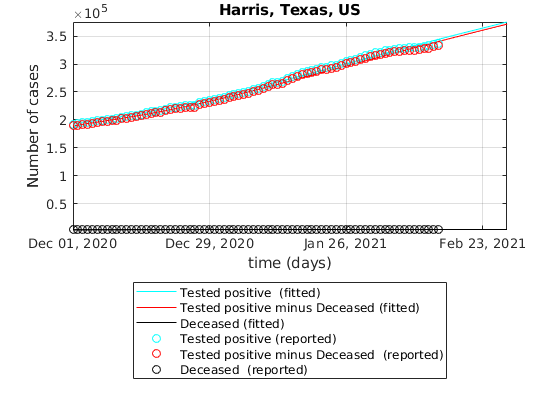

         Combined_Key      
    _______________________

    "Maricopa, Arizona, US"



Population = 4485414 


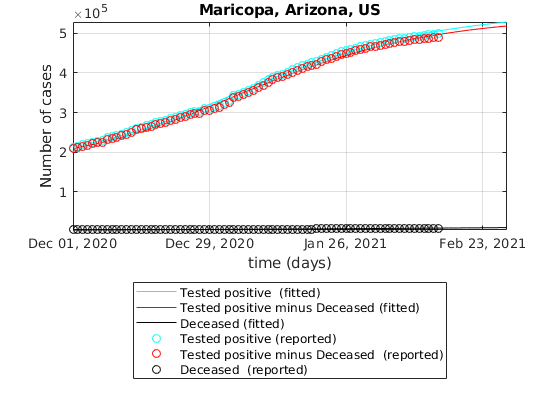

       Combined_Key    
    ___________________

    "Dallas, Texas, US"



Population = 2635516 


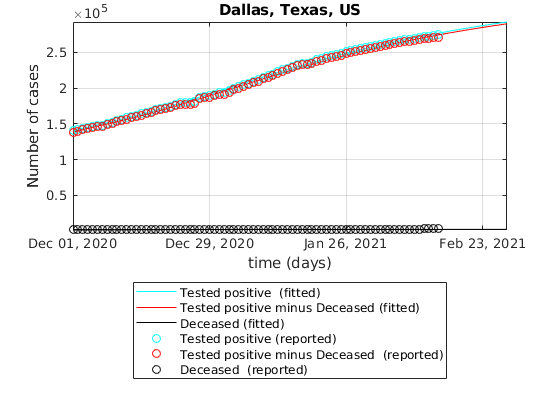

         Combined_Key     
    ______________________

    "Broward, Florida, US"



Population = 1952778 


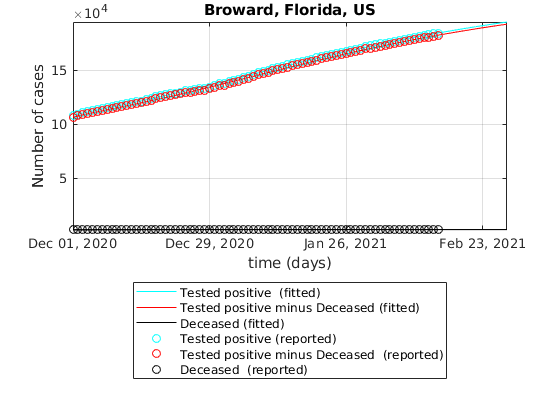

         Combined_Key     
    ______________________

    "Queens, New York, US"



Population = 2253858 


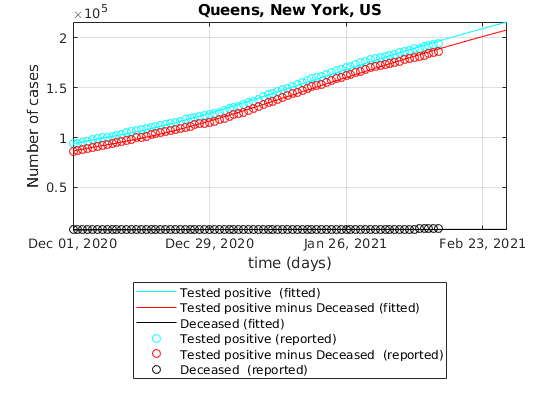

        Combined_Key     
    _____________________

    "Kings, New York, US"



Population = 2559903 


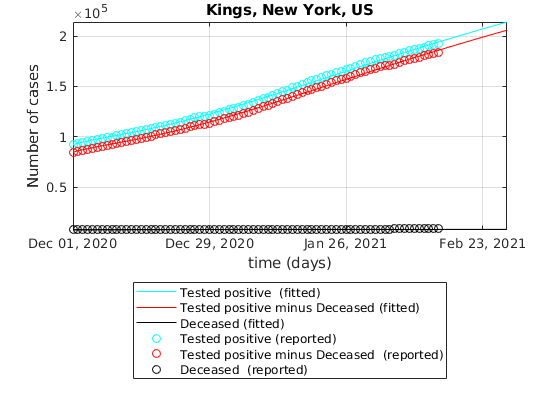

% for ii = 2:numel(tableConfirmed.Combined_Key)
for ii = [215, 384, 642, 2800, 110, 2756, 347,  1943, 1925] % select place with many confirmed cases
    Location = tableConfirmed.Combined_Key(ii);
    
    indC = find(strcmpi(tableConfirmed.Combined_Key,Location)==1);
    indD = find(strcmpi(tableDeaths.Combined_Key,Location)==1);
    
    Deaths = table2array(tableDeaths(indD,13:end));
    Confirmed = table2array(tableConfirmed(indC,12:end));
    Npop= table2array(tableDeaths(indD,12)); % p
    
    if Npop == 0
        %         warning('Unreal population found. A dummy variable is used instead')
        Npop = 1e6; % dummy population is used instead
    end
    
    time = timeRef;
    indT = find(time>=tStart & time <=tEnd);
    Deaths = Deaths(indT);
    time = time(indT);
    Confirmed = Confirmed(indT);
    
    
    
    disp(tableConfirmed(indC,11));
    fprintf(['Population = ',num2str(Npop),' \n'])
    % Definition of the first estimates for the parameters
    alpha_guess = 0.1;
    beta_guess = 0.8; % Infection rate
    LT_guess = 5; % latent time in days
    Q_guess = 0.5; % rate at which infectious people enter in quarantine
    lambda_guess = [0.08,0.1,0.1]; % recovery rate
    kappa_guess = [0.07,0.03,10]; % death rate
    
    guess = [alpha_guess,...
        beta_guess,...
        1/LT_guess,...
        Q_guess,...
        lambda_guess,...
        kappa_guess];
    
    E0 = 0.25*Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
    I0 = 0.5*E0; % Initial number of infectious cases. Unknown but unlikely to be zero.
    Q0 = Confirmed(1)-Deaths(1);
    R0 = 0; % set as zero since not explicitely used
    D0 = Deaths(1);
    
    % Parameter estimation with the lsqcurvefit function
    [alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun] = ...
        fit_SEIQRDP(Confirmed-Deaths,[],Deaths,Npop,E0,I0,time,guess,'Display','off');
    
    dt = 1/24; % time step
    time1 = datetime(time(1), 'Locale', 'en_US'):dt:datetime(time(end)+datenum(14), 'Locale', 'en_US');
    N = numel(time1);
    t = [0:N-1].*dt;
    [S,E,I,Q,R,D,P] = ...
        SEIQRDP(...
        alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t,lambdaFun,kappaFun);
    
    
    figure
    semilogy(time1,Q+R+D,'c',time1,Q+R,'r',time1,D,'k');
    hold on
    semilogy(time,Confirmed,'co',time,Confirmed-Deaths,'ro',time,Deaths,'ko');
    % ylim([0,1.1*Npop])
    ylabel('Number of cases')
    xlabel('time (days)')
    leg = {'Tested positive  (fitted)','Tested positive minus Deceased (fitted)',...
        'Deceased (fitted)',...
        'Tested positive (reported)',...
        'Tested positive minus Deceased  (reported)','Deceased  (reported)'};
    legend(leg{:},'location','southoutside')
    set(gcf,'color','w')
    grid on
    axis tight
    title([Location])
    set(gca,'yscale','lin')
    
    % PLot the pseudo death rate
    %         checkRates(time,Confirmed-Deaths,[],Deaths,kappaFun,lambdaFun,Kappa1,Lambda1);
    pause(0.01)
    
end